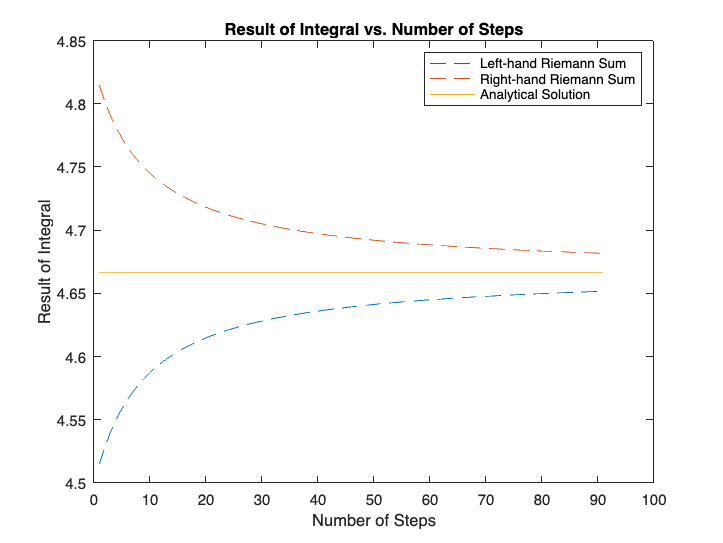

a = 0;
b = 3;

analytical_solution = 14 / 3;

Ln = NaN(1, 91);
Rn = NaN(1, 91);

for n = 10:100
    dx = (b - a) / n;
    Ln(n - 9) = sum(sqrt((a + (linspace(1, n, n) - 1) * dx) + 1) * dx);
    Rn(n - 9) = sum(sqrt((a + linspace(1, n, n) * dx) + 1) * dx);
end

figure;
plot(1:91, Ln, "--", "DisplayName", "Left-hand Riemann Sum");
hold on
plot(1:91, Rn, "--", "DisplayName", "Right-hand Riemann Sum");
plot(1:91, analytical_solution * ones(1, 91), "-", "DisplayName", "Analytical Solution");
legend show
xlabel("Number of Steps")
ylabel("Result of Integral")
title("Result of Integral vs. Number of Steps")